# Recycling Analysis Demo

Use WasteAnalysis function to obtain the potencial saving cost of waste recycling

#### Read the Data Model

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Set the parameters

if ~data.isWaste
    disp('The model has NOT waste');
    return
end
WasteFlows=convertCharsToStrings(data.WasteFlows);
ActiveWaste=convertStringsToChars(WasteFlows(1));
States=convertCharsToStrings(data.StateNames);
State=convertStringsToChars(States(1));
CostTables='DIRECT';
if data.isResourceCost
    CostTables='ALL';
    Samples=convertCharsToStrings(data.SampleNames);
    ResourceSample=convertStringsToChars(Samples(1));
end

#### Get Waste Analysis Results

res=WasteAnalysis(data,'ActiveWaste',ActiveWaste,'State',State,...
    'CostTables',CostTables,'ResourceSample',ResourceSample);

#### Show the Results

Show the waste allocation table and display de waste recycling graphs for direct and generalizad costs

ShowResults(res,'Table','wa');

Waste Allocation Table  (%)

 Key         QCND
——————————————————
 BLR        94.38
 TRB         2.25
 IHE         2.07
 PMP         1.29
 ENV       100.00



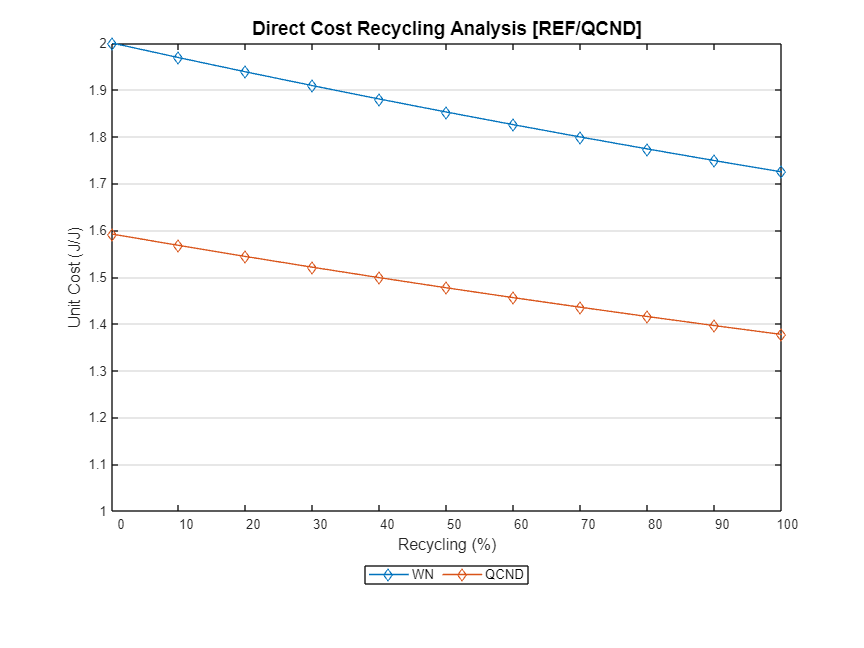

ShowGraph(res,'Graph',cType.Tables.WASTE_RECYCLING_DIRECT);

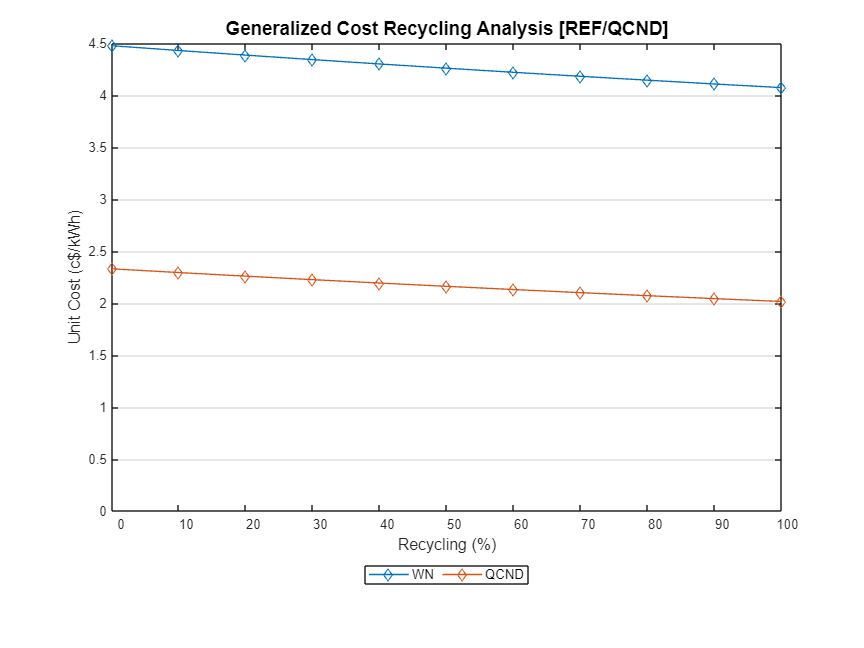

ShowGraph(res,'Graph',cType.Tables.WASTE_RECYCLING_GENERAL);